format shortG


# 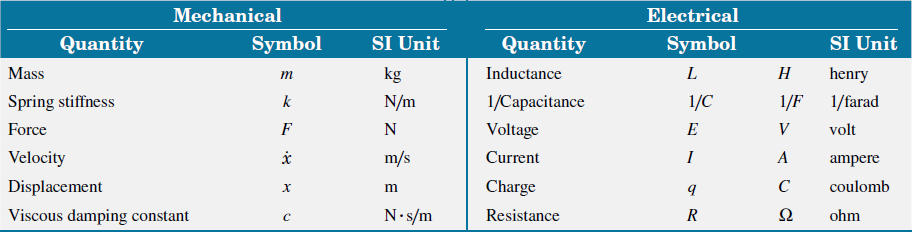

# Udæmpede frie svingninger

$m$ er massen [kg]

$k$ er fjederkonstanten [N/m]

    
$$k_{serie} = \frac{1}{\frac{1}{K1} + \frac{1}{K2} }$$


    
$$k_{paralel} = K_1 + K_2$$


$\omega_n$ er egensvingningen eller vinkelhastigheden [rad/s]

x er afstand [m]

$t$ er tiden [s]

$\dot x = V$ er hastigheden [m/s]

$\ddot x = a$ er accelerationen [m/s^2]

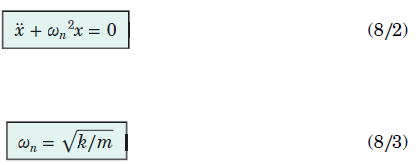

## Løsning

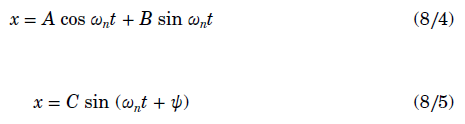

**for t = 0 gælder**


$$C = \frac{\dot x_0}{\omega_n \cdot cos(\psi)}$$


psi = atan(x_0 * omega_n / V_0)

A = x_0 
B = V_0 / omega_n

C = sqrt(A^2 + B^2 )

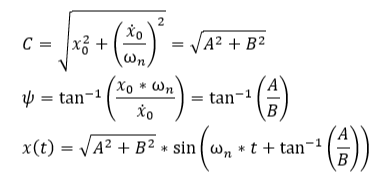

### Vinkelhastighed, frekevens, periode


$$\omega_n = \sqrt{\frac{k}{m}} =2\pi \cdot f_n$$



$$f_n = \frac{\omega_n}{2\pi}$$



$$\tau_n = \frac{1}{f_n} = \frac{2\pi}{\omega_n}$$


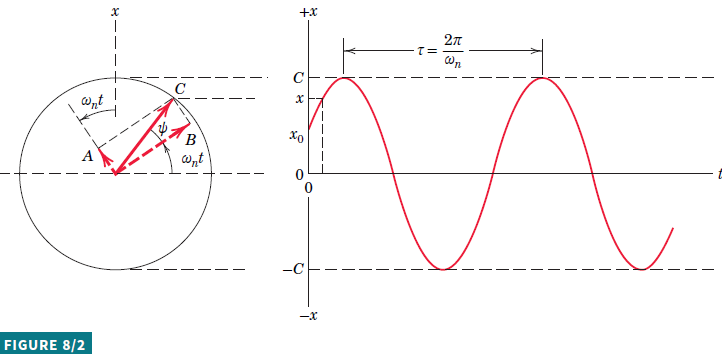

clear 

disp('Vi opstiller vores data')
k = 32 % N/m    %* u.N / u.m
m = 8 % kg      %* u.kg
c = 20 %N*s/m   %* u.N * u.s / u.m
t0 = 0 %s       % Start tiden 
t1 = 2          % Slut tiden
disp('Egensvingningen findes')
w_n = sqrt(k/m) %egensvingningen

disp('Dæmpningsrationen findes')
zeta = c/(2 * m * w_n) % viscous damping factor or damping ratio

if separateUnits(zeta) < 1
    disp('systemet er underdamped')
elseif separateUnits(zeta) == 1
    disp('systemet er critical damped')
else
    disp('systemet er overdamped')
end

disp('Finder den naturlige dæmpnings frekvens')
w_d = w_n*sqrt(1-zeta^2) % damped natrual freqancy

syms psi C_s f(t) t f_1(t)

disp('Værdierne ved t = 0 findes for sted og hastighedsfunktionen')
x_0 = 0.2 % m %start stedet
V_0 = 0 % m/s %start hastigheden

disp('Ligning (8/12) opstilles og benyttes til at finde forskydningen')
f(t) = C_s * exp(-zeta * w_n * t) * (sin(w_d * t + psi)) % Sted funktionen for underdæmpede svininger ligning (8/12) %

disp('Ved at differentier forskydningsligningen får vi hastighedes ligningen')
f_1(t) = diff(f(t), t) %% Hastigheds funktionen

disp('Vi løser ligningssystemet for C_s og psi')
x = [f(t0) == x_0, f_1(t0) == V_0]; %% sættes op i et array så der kan solves for de 2 ukendte. 
% start værdiger t = 0 x = 0.2 osv hastighed er 0 når t = 0

S = solve(x, psi, C_s); %Solver for psi og C_s i vores x lignings system


%udpakker og vudere værdierne fra struct
psi = vpa(S.psi, 5) %Vpa
C_s = vpa(S.C_s, 5) %Vpa

fprintf('Vi erstatter C_s og psi i forskydningsligningen \nog finder restultatet t = %f', t0)

f(t) = C_s(2)*exp(-zeta * w_n * t)*(sin(w_d * t + psi(2))); % Indsætter vores nye værdiger i funktionenn så vi for en real ligning (2) er for at få det korrekte indeks 

disp(' ')
fprintf('Placeringen af kassen til tiden t = %f er således:', t1)
x_2 = vpa(f(t1), 3)

disp('Der plottes en kurve over bevægelsen')
fplot(f(t), [t0, t1 + 3]) %plot 
hold on
% yline(double(x_2), '--r')
plot(t1, double(x_2), 'or')
xline(0)
yline(0)
ylabel('Forskydning x($m$)', Interpreter='latex')
xlabel('Tiden t($s$)', Interpreter='latex')
grid()
hold off



# Dæmpede svigninger

$c$ er viscous damping coefficient [N s / m]

$F_d$ er dæmpningskraften [N] er altid modsat rettede bevægelsen.

$\zeta$ er viscous damping factor or damping ratio [-]

$\omega_d$ er damped natural frequency [rad/s]

$\tau_d$ er damped period [1/s]


$$F_d = - c \cdot \dot x$$
 

kontroler for dæmpning med dæmpningsrationen

$\zeta < 1$ **underdamped **(Der kommer svigninger) 

                 
$$\omega_d = \omega_n \sqrt{1 - \zeta^2}$$


**Løsning: **

$\zeta = 1$ **Critical damped** $\lambda_1$ og $\lambda_2$ er ens reelle negative tal (rammer hurtige ligevægt end overdamped)

**Bestem først hvilken type dæmpning der er**

**Løsning:** 

$\zeta > 1$ **Overdamped** (Ingen svigninger) $\lambda_1$ og $\lambda_2$ er forskellige reelle negative tal - ingen periode

## Opstil ligningen

eller basic ligningen


$$\ddot x + \frac{c}{m} \dot x + \frac{k}{m}  x = 0
$$


**characteristic equation**

## Løsning

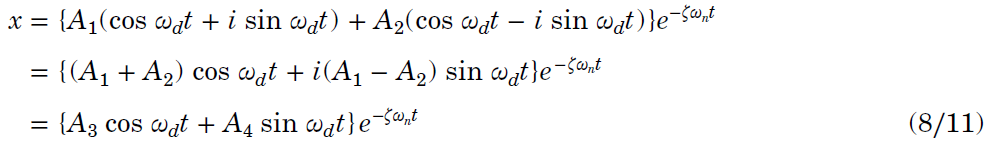

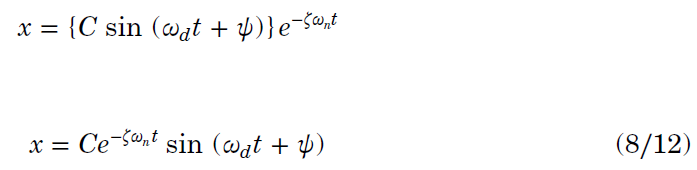

Kritisk dæmpet

Under dæmpet


$$\omega_d = \omega_n \sqrt{1 - \zeta^2}$$



$$\tau_d = \frac{2\pi}{\omega_d} = \frac{2\pi}{\omega_n \sqrt{1 - \zeta^2}} $$
 

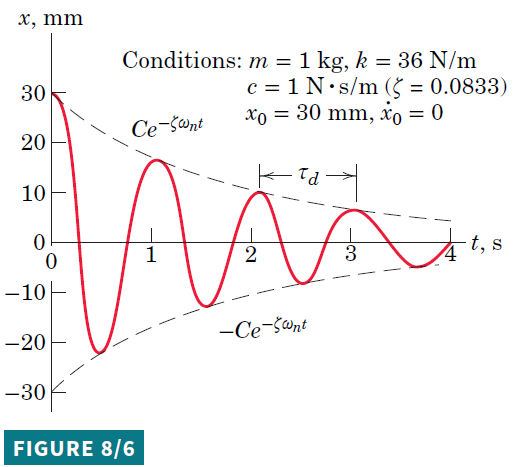

# Drevne dæmpede svigninger

$\omega$ er frekvensen af ydre kraft [1/s]

$X$ er Amplituden af svigningen

**standard form**

**Base**

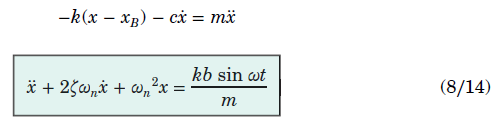

**Undamped Forced Vibration side 271**

**Damped Forced Vibration**

**basic differential equation**

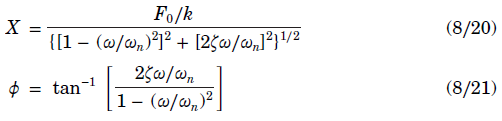

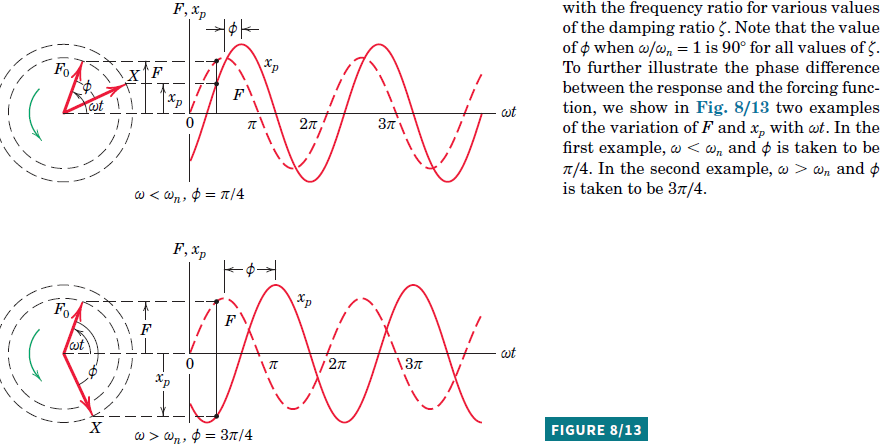

Opstil FBD og KD for situationen (brug evt excalidraw)

clear
format shortG

syms c x F_0 omega t k m

syms x(t)

x_1 = diff(x(t), t)

$$x\_1 = \frac{\partial }{\partial t}x\left(t\right)$$


x_2 = diff(x_1, t)

$$x\_2 = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$


disp('Uden ydre kraft')

Uden ydre kraft


displayFormula('0 == x_2 + c/m * x_1 + k/m * x')

$$0=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\frac{c}{m}\,\frac{\partial }{\partial t}x\left(t\right)+\frac{k}{m}\,x\left(t\right)$$


disp('Med ydre kraft')

Med ydre kraft



displayFormula('F_0 * sin(omega * t) / m == x_2 + c/m * x_1 + k/m * x')

$$\frac{F_{0}\,\sin\left(\omega \,t\right)}{m}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\frac{c}{m}\,\frac{\partial }{\partial t}x\left(t\right)+\frac{k}{m}\,x\left(t\right)$$